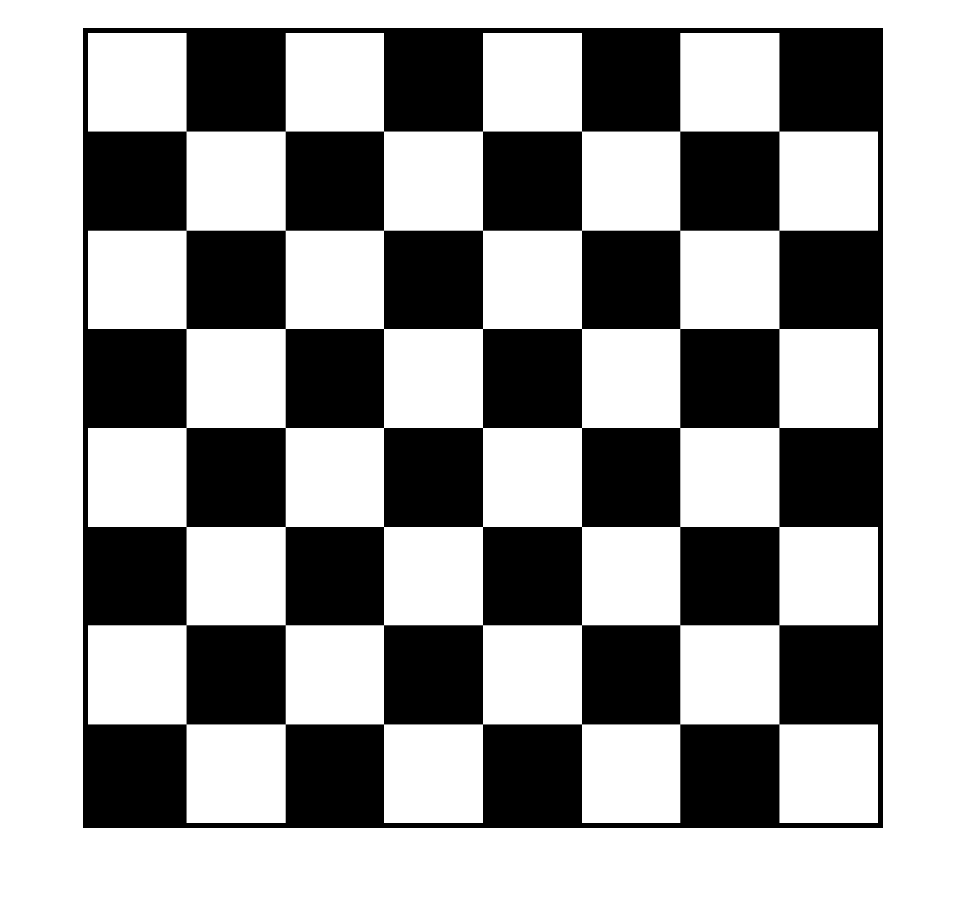

close all; 
clear all; 
clc
%% part 0 - Construct necessary form of images
im=imread('chessboard00.png'); % Step 0: Read Image
figure ;imshow(im);

im1=im2double(im);
figure ;imshow(im1);

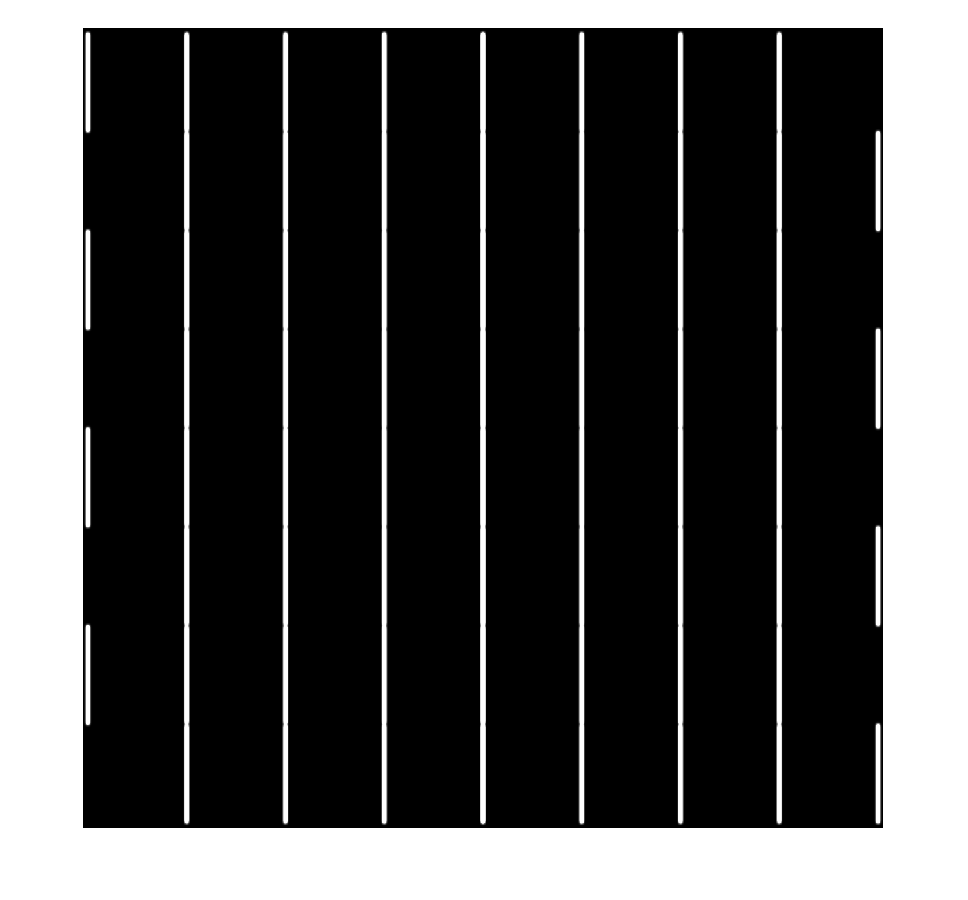

dx = [-1 0 1; -1 0 1; -1 0 1]; % image derivatives
dy = dx';
Ix = imfilter(im1, dx);    % Step 1: Compute the image derivatives Ix and Iy
Iy = imfilter(im1, dy);
g = fspecial('gaussian',9,2); % Step 2: Generate Gaussian filter 'g' of size 9x9 and standard deviation Sigma=2.
Ix2 = imfilter(Ix.^2, g); % Step 3: Smooth the squared image derivatives to obtain Ix2, Iy2 and IxIy
figure;imshow(Ix2);

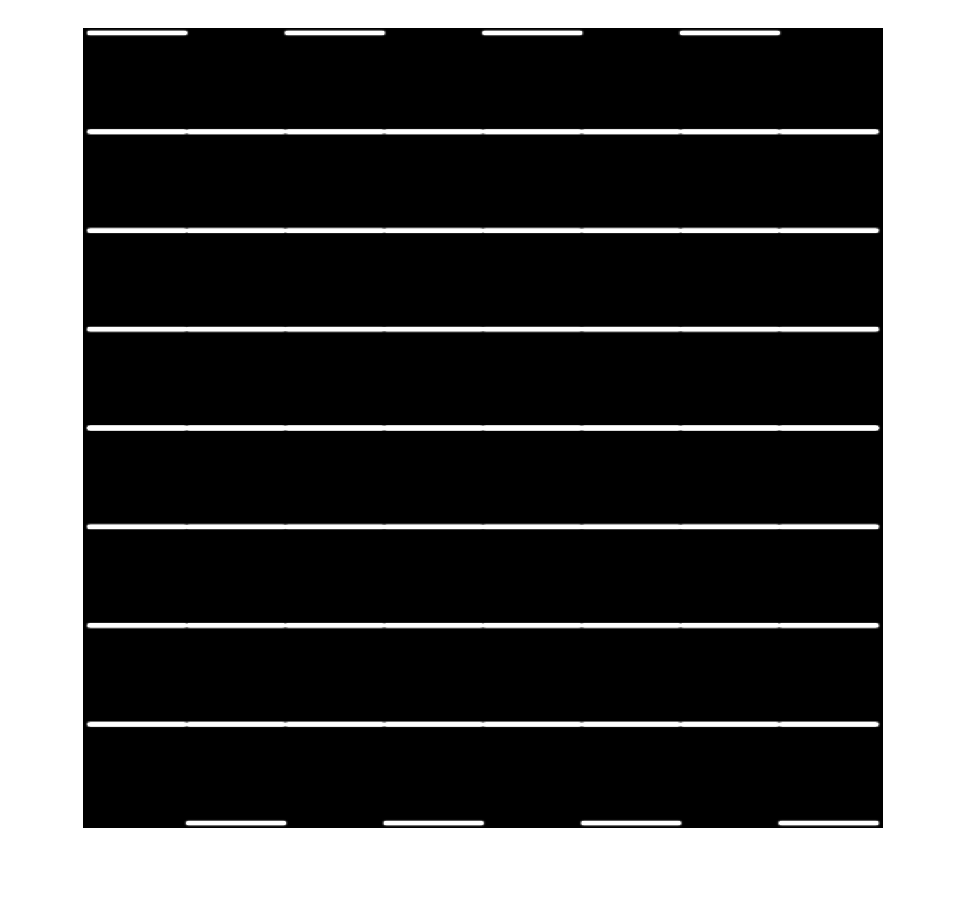

Iy2 = imfilter(Iy.^2, g);
figure;imshow(Iy2);

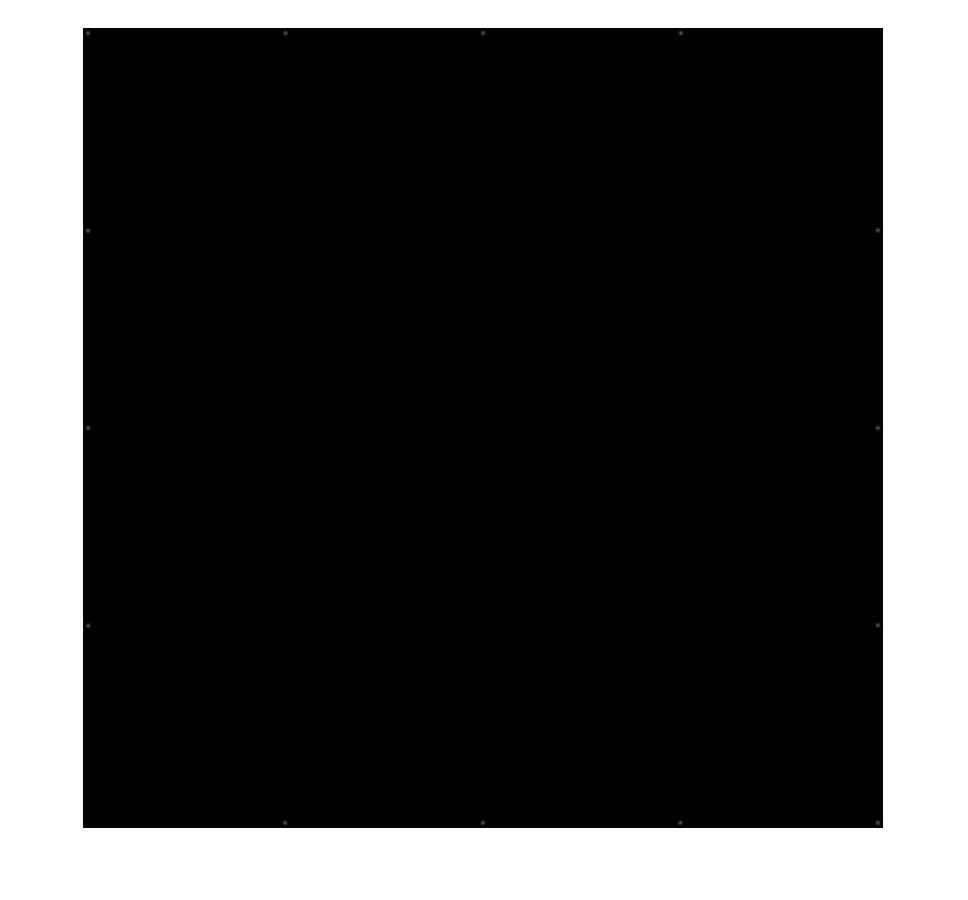

IxIy = imfilter(Ix.*Iy, g);
figure;imshow(IxIy); %Display the images obtained in different steps

%% part 1- Compute Matrix E which contains for every point the value
[r c]=size(Ix2);
E = zeros(r, c); % Compute matrix E
tic
for i=2:1:r-1 
    for j=2:1:c-1
     Ix21=sum(sum(Ix2(i-1:i+1,j-1:j+1)));
     Iy21=sum(sum(Iy2(i-1:i+1,j-1:j+1)));
     IxIy1= sum(sum(IxIy(i-1:i+1,j-1:j+1)));
     M=[Ix21 IxIy1;IxIy1 Iy21]; %(1) Build autocorrelation matrix for every singe pixel considering a window of size 3x3
     E(i,j)=min(eig(M)); %(2)Compute Eigen value of the autocorrelation matrix and save the minimum eigenvalue as the desired value.
    end
end
t=toc;
disp('time needed for calculating E matrix');

time needed for calculating E matrix


disp(t);

   53.5271



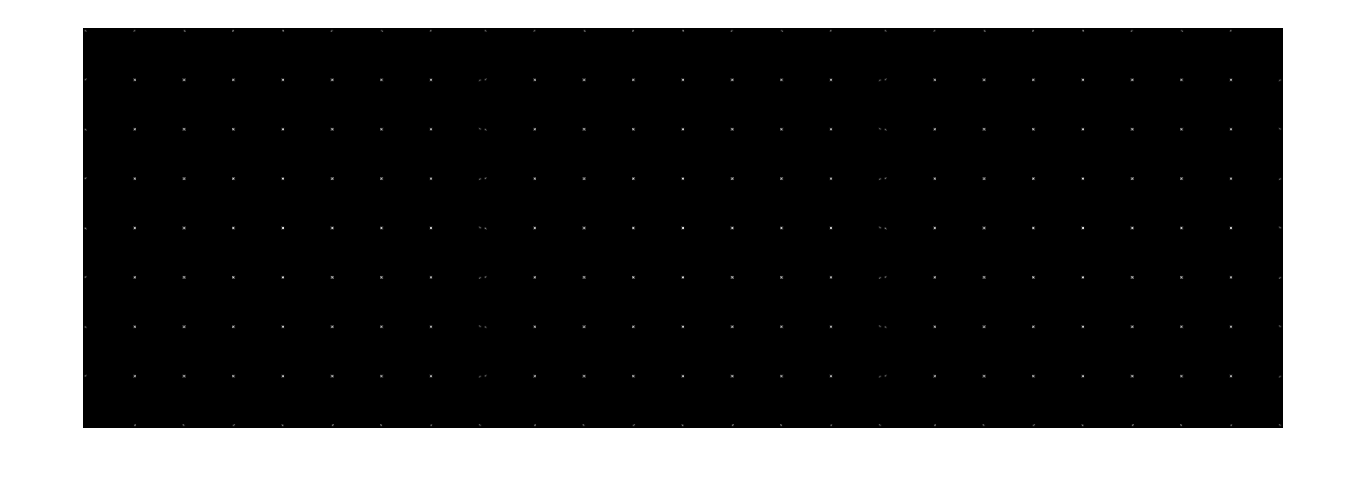

figure, imshow(mat2gray(E)); % display result

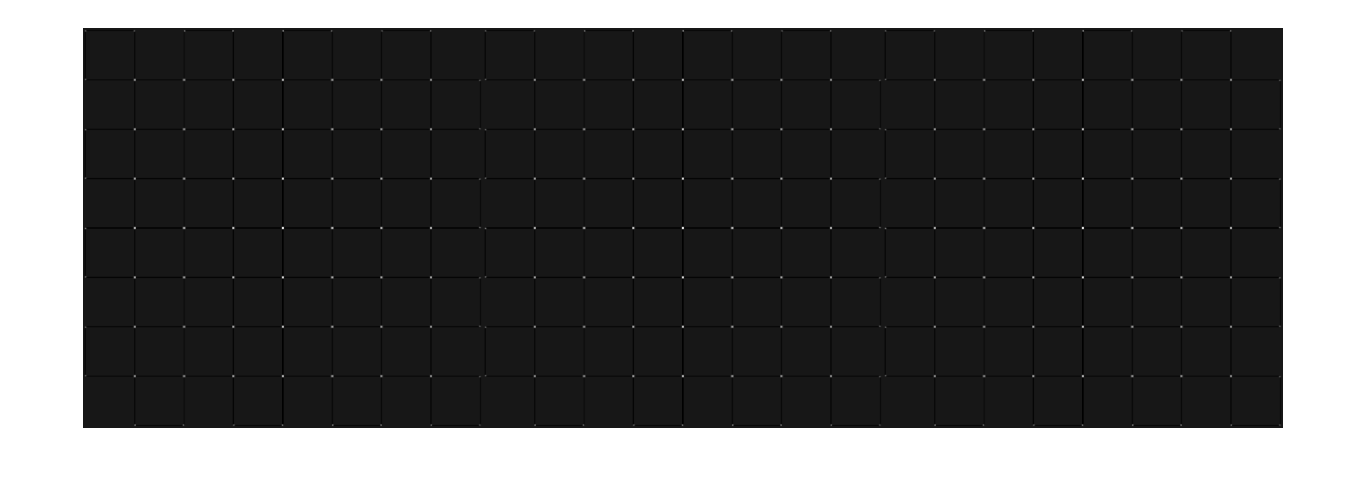

%% part 2- Compute Matrix R which contains for every point the cornerness score.
[r c]=size(Ix2);
R = zeros(r, c);
k = 0.04;
tic
for i=2:1:r-1
    for j=2:1:c-1
     Ix21=sum(sum(Ix2(i-1:i+1,j-1:j+1)));
     Iy21=sum(sum(Iy2(i-1:i+1,j-1:j+1)));
     IxIy1= sum(sum(IxIy(i-1:i+1,j-1:j+1)));
     M=[Ix21 IxIy1;IxIy1 Iy21];
     R(i,j)=det(M)-k*trace(M).^2; %(1) Build autocorrelation matrix for every singe pixel considering a window of size 3x3
    end
end
t=toc;
figure, imshow(mat2gray(R)); % display result

disp('time for calculating R matrix');

time for calculating R matrix


disp(t);

   55.8280



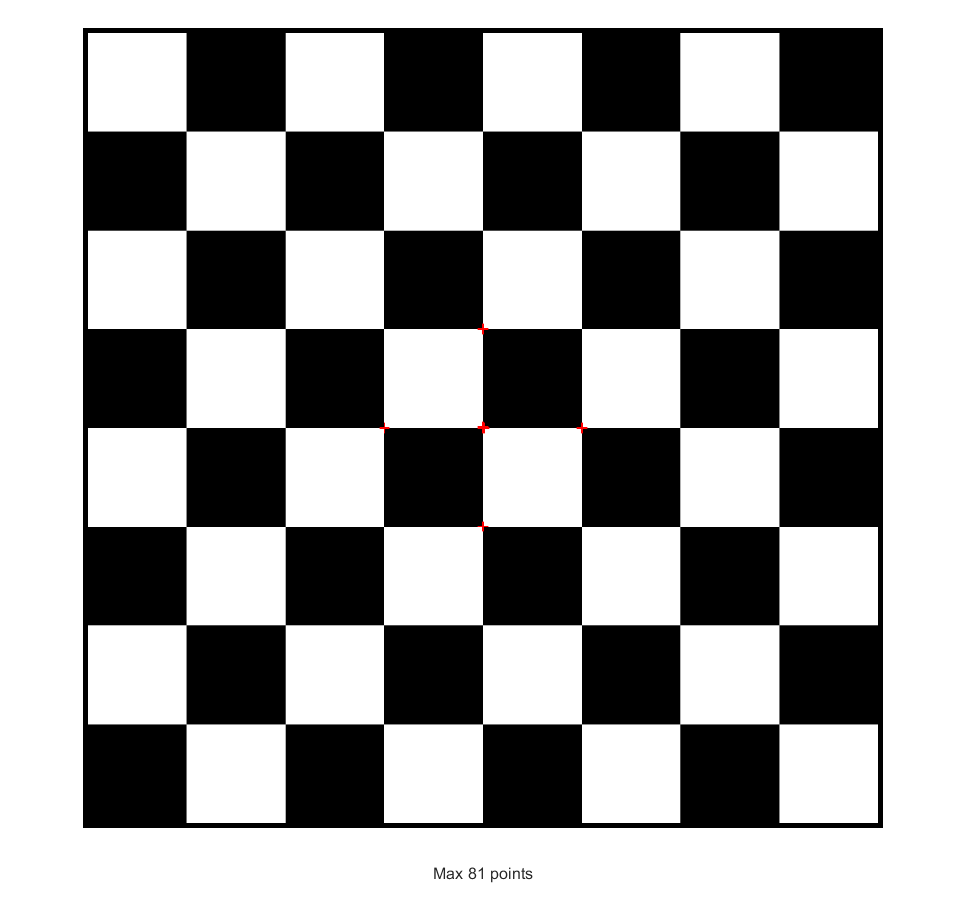

%% Part 3 - Select for E and R the 81 most salient points
% Get the coordinates with maximum cornerness responses
% Write a function to obtain the 81 most salient points
numPts = 81;
[sortR,RIX] = sort(R(:),'descend');
[a, b] = ind2sub([r c],RIX);%The mapping from linear indexes to subscript equivalents for the matrix
figure; imshow(im1, []); hold on; xlabel('Max 81 points');% Get the coordinates with maximum cornerness responses     
for i=1:81, 
	plot(a(i), b(i), 'r+'); 
end  

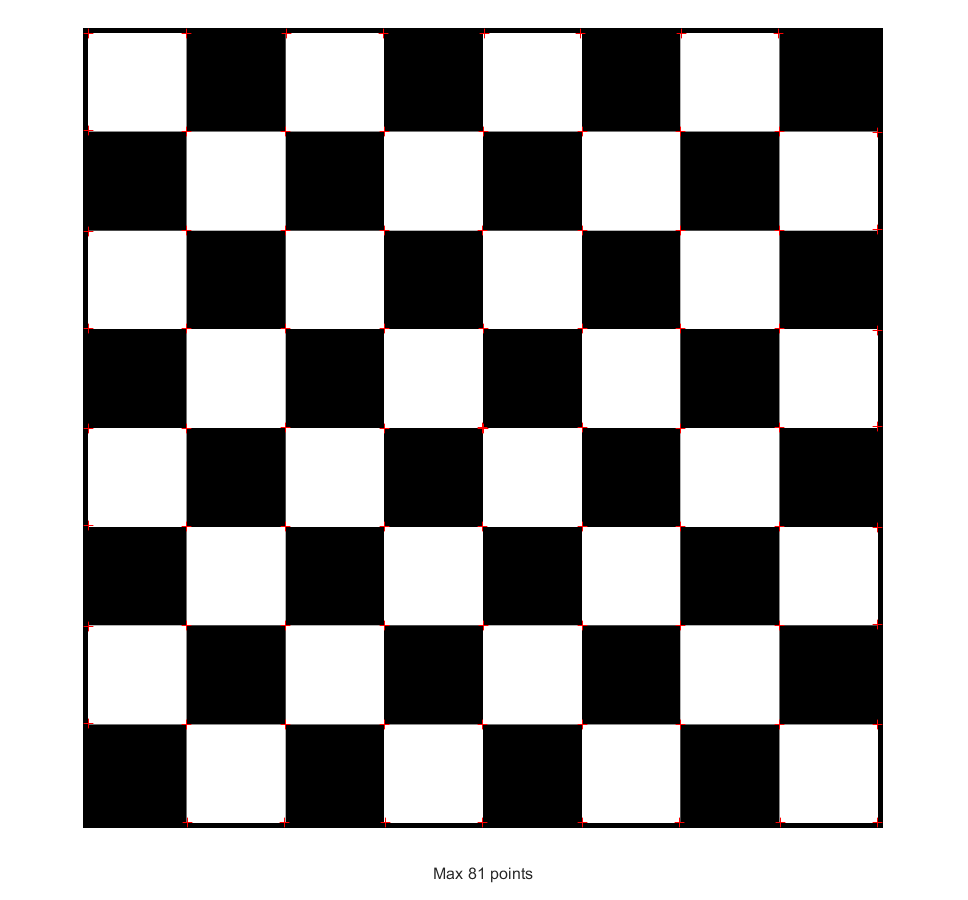

%% Part 4 - Build  a  function  to  carry  out  non-maximal  suppression  for  E  and
% R.  Again, the 81 most salient points using a non-maximal suppression of 11×11 pixels.
R1= ordfilt2(R,121,ones(11));% Get the coordinates with maximum cornerness responses
R2=(R1==R) & (R > 10);
[sortR2,R2IX] = sort(R2(:),'descend');
[a, b] = ind2sub([r c],R2IX); %The mapping from linear indexes to subscript equivalents for the matrix
figure; imshow(im1, []); hold on; xlabel('Max 81 points'); %labeling along with X axis    
for i=1:81 
	plot(a(i), b(i), 'r+'); 
end